# Lab by Mikołaj Suchoń

clear
load("termogram.mat")
size(data)

ans =    640   640   304


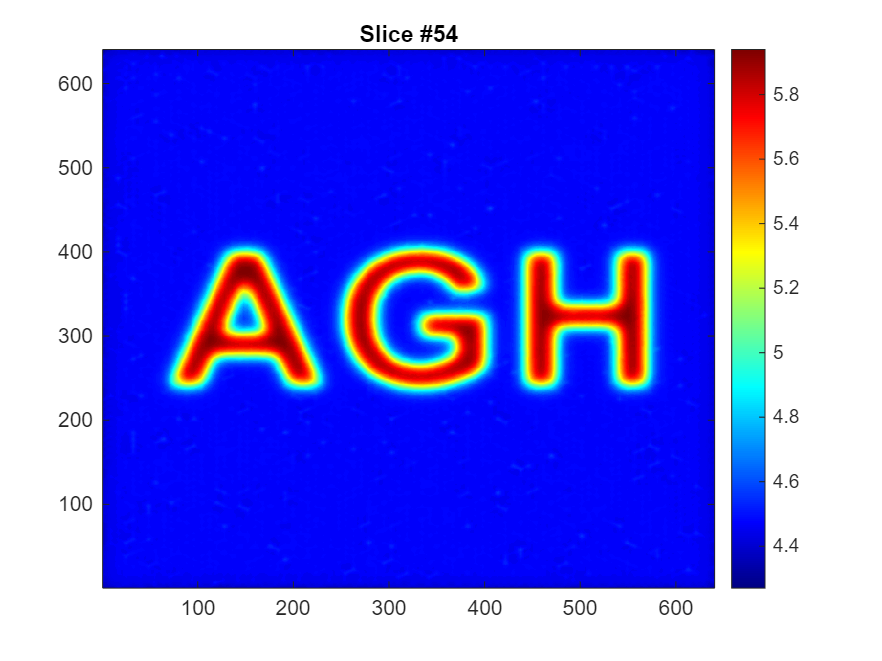

slice_index = 54;  % Change this from 1 to 304 to view different slices

imagesc(data(:, :, slice_index));  % Display the selected 2D slice
colormap('jet');                   % Choose your preferred colormap
colorbar;                          % Add colorbar to indicate data values
title(['Slice #' num2str(slice_index)]);
set(gca, 'YDir', 'normal');        % Set Y axis to normal (not reversed)

% figure;
% colormap('jet');         % Set colormap for temperature visualization
% colorbar;                % Show colorbar to indicate temperature scale
% 
% for t = 1:size(data, 3)
%     imagesc(data(:, :, t));      % Show slice at time t
%     title(['Temperature at Time Step ' num2str(t)]);
%     set(gca, 'YDir', 'normal');  % Y axis from bottom to top
%     drawnow;                     % Force MATLAB to update the figure immediately
%     pause(0.01);                 % Pause for 10 ms between frames
% end

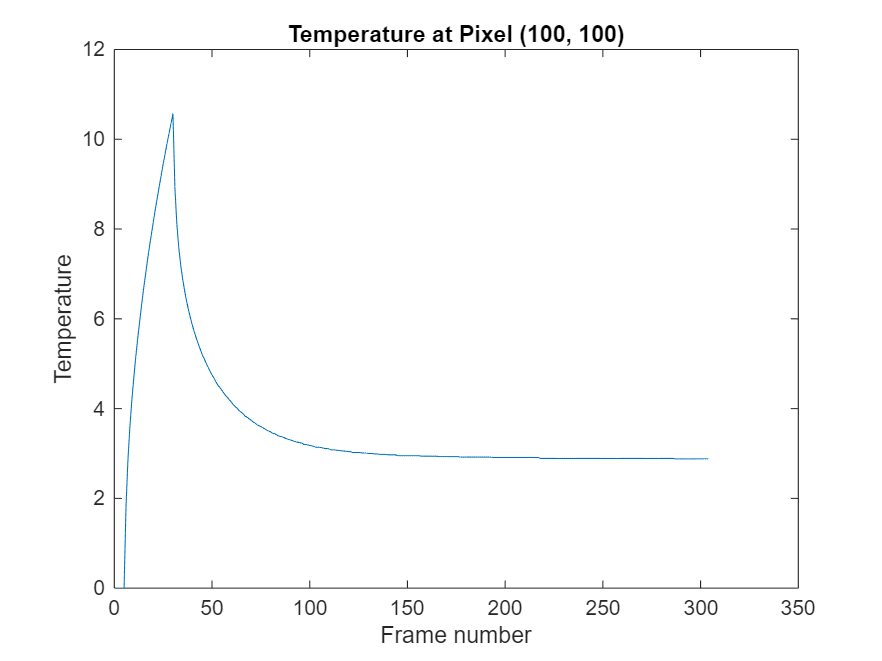

% Assume 'data' is your 640x640x304 temperature tensor

temp_series = squeeze(data(100, 100, :));  % Extract time series at pixel (100,100)

plot(temp_series);                         % Plot temperature vs time
xlabel('Frame number');                       % Label x-axis
ylabel('Temperature');                     % Label y-axis
title('Temperature at Pixel (100, 100)');  % Optional title

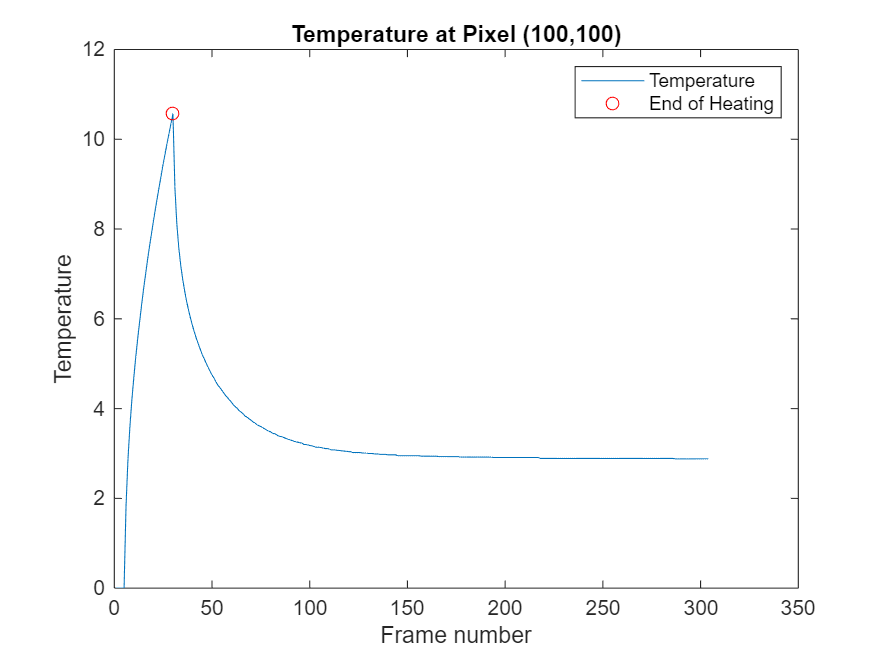

% Find the index of maximum temperature (end of heating)
[max_temp, max_idx] = max(temp_series);

% Optionally, show the result
plot(temp_series);
xlabel('Frame number');                    
ylabel('Temperature');
title('Temperature at Pixel (100,100)');
hold on;
plot(max_idx, max_temp, 'ro');  % Mark end of heating
legend('Temperature', 'End of Heating');

% Example: cutoff frame index (e.g., determined from previous max)
frame_cutoff = max_idx;  % or assign manually

% Trim the data from frame_cutoff to the end
cooling_data = data(:, :, frame_cutoff:end);

% Get new dimensions
[rows_cool, cols_cool, frames_cool] = size(cooling_data);

% Display results
disp(['Cooling data dimensions: ', num2str(rows_cool), ' x ', num2str(cols_cool), ' x ', num2str(frames_cool)]);

Cooling data dimensions: 640 x 640 x 275


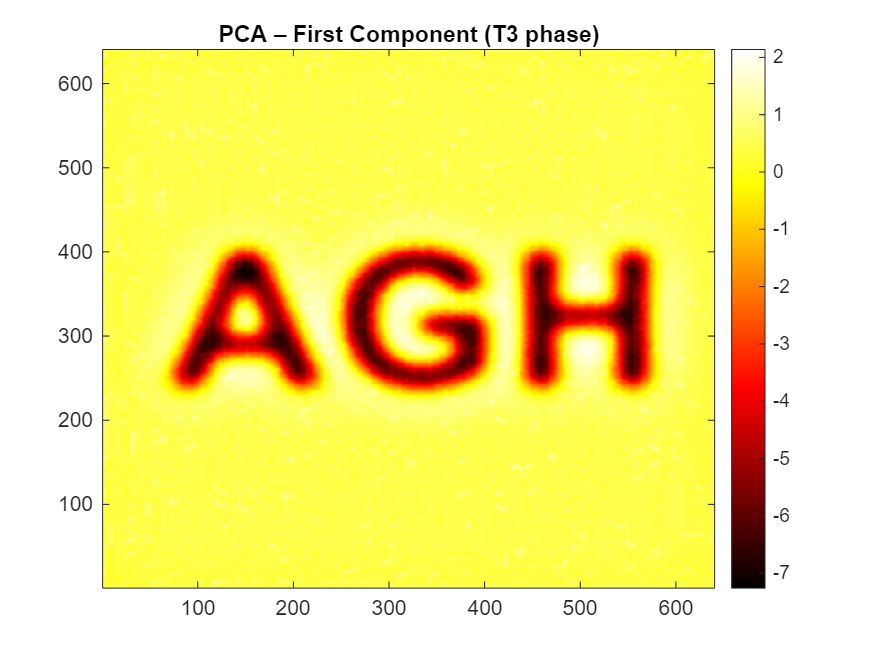

% 7. PCA on cooling phase (T3)
reshaped = reshape(cooling_data, rows_cool * cols_cool, frames_cool);
% Centering data
mean_signal = mean(reshaped, 2); % mean for each pixel
centered_data = reshaped - mean_signal;
% PCA: columns = frames (variables), rows = pixels (observations)
[coeff, score, ~] = pca(centered_data);
% First PCA component
pca_image = reshape(score(:,1), rows_cool, cols_cool);
%%
% Displaying PCA
figure;
imagesc(pca_image);
colormap hot; colorbar; set(gca, 'YDir', 'normal'); title('PCA – First Component (T3 phase)');

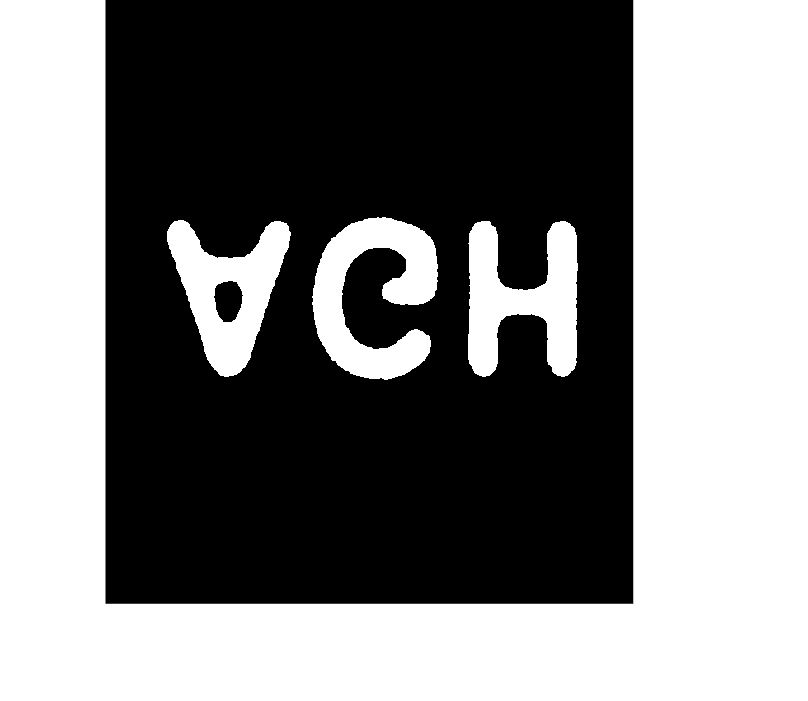

% Assume 'pca_image' is your PCA result (2D matrix)

% Step 1: Normalize to [0,1] for binarization
pca_norm = mat2gray(pca_image);  % Normalize values to [0, 1]

% Step 2 (optional): Invert if the feature of interest (e.g., AGH string) is darker
pca_inverted = 1 - pca_norm;     % Invert so that the feature becomes brighter

% Step 3: Compute threshold using Otsu's method
threshold = graythresh(pca_inverted);  % Automatically finds optimal threshold

% Step 4: Binarize the image
binary_image = imbinarize(pca_inverted, threshold);

% Step 5: Display the result
imshow(binary_image);
title('Binarized PCA Image');

% Assume 'binary_image' is your binarized image (logical matrix)
% where defect pixels are 1 (white)

% Step 1: Count number of defect pixels
num_defect_pixels = sum(binary_image(:));

% Step 2: Compute area per pixel in mm²
pixel_size_mm = 0.15625;            % mm
pixel_area_mm2 = pixel_size_mm^2;   % mm² per pixel

% Step 3: Total defect area
defect_area_mm2 = num_defect_pixels * pixel_area_mm2;

% Display result
disp(['Defect Area = ' num2str(defect_area_mm2) ' mm²']);

Defect Area = 945.2148 mm²


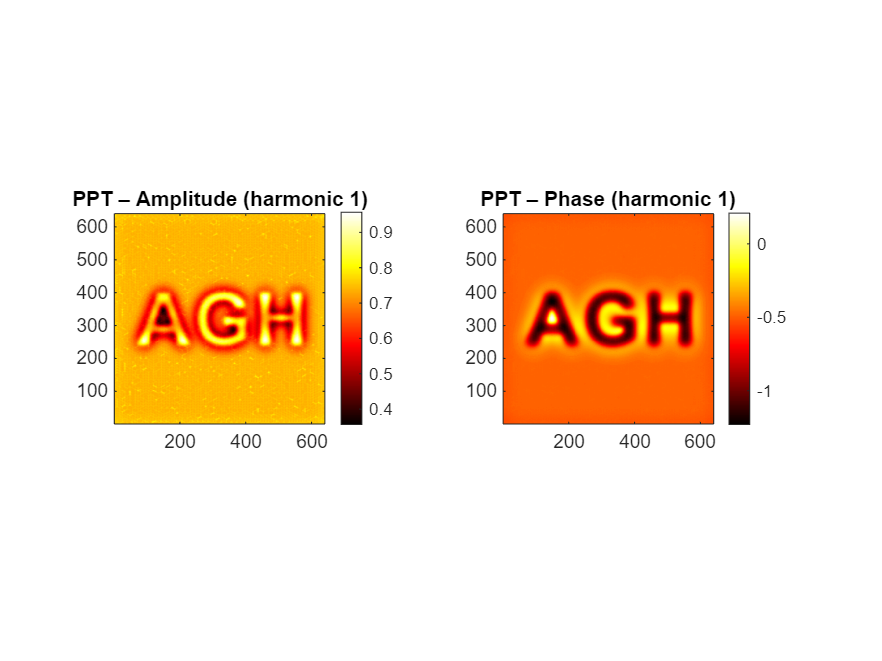

% 10. PPT (Pulse Phase Thermography)
% Define basic variables
L = size(cooling_data,3); % Length of the signal
% FFT
Y = fft(cooling_data,[],3);
% Single-sided spectrum
P2 = abs(Y/L);
P1 = P2(:,:,1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
% Assign amplitude and phase
Amplitude = P1;
Phase = angle(Y(:,:,1:floor(L/2)+1));
% Choose harmonic for analysis (e.g., 2 = 1st harmonic)
harmonic_idx = 2;
Amplitude_img = Amplitude(:,:,harmonic_idx);
Phase_img = Phase(:,:,harmonic_idx);
% Visualization
figure;
subplot(1,2,1);
imagesc(Amplitude_img); set(gca, 'YDir', 'normal');
colormap hot; colorbar;
axis image; title(['PPT – Amplitude (harmonic ', num2str(harmonic_idx-1), ')']);
subplot(1,2,2);
imagesc(Phase_img); set(gca, 'YDir', 'normal');
colormap hot; colorbar;
axis image; title(['PPT – Phase (harmonic ', num2str(harmonic_idx-1), ')']);

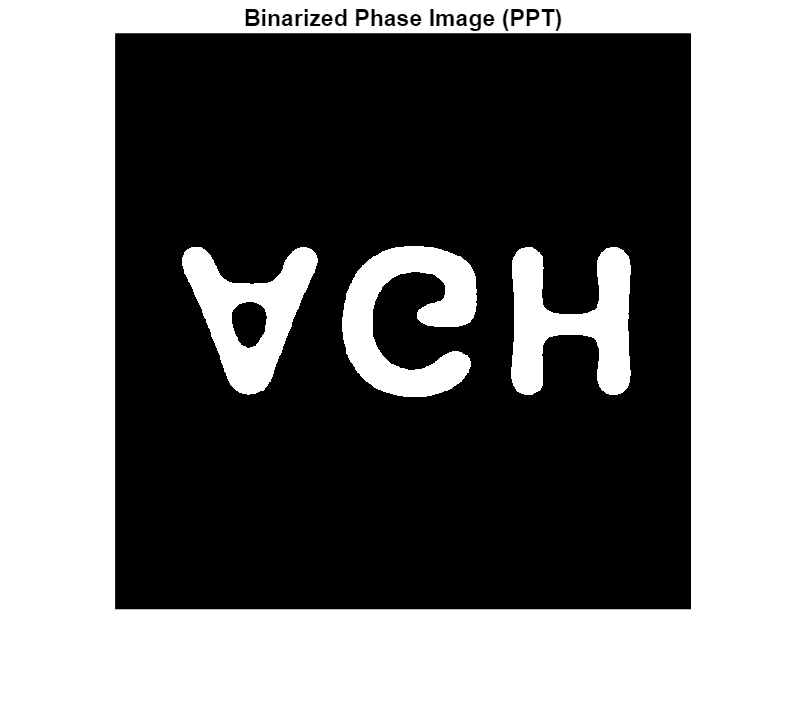

% Assume Phase_img is your phase image with values in [-pi, pi]

% Step 1: Normalize to [0, 1]
phase_norm = (Phase_img + pi) / (2 * pi);  % Shift from [-pi, pi] to [0, 1]

% Step 2 (optional): Invert if the AGH region has lower values
phase_inverted = 1 - phase_norm;

% Step 3: Apply Otsu’s thresholding
threshold = graythresh(phase_inverted);         % Compute global threshold
binary_phase = imbinarize(phase_inverted, threshold);  % Binarize
figure
% Step 4: Display result
imshow(binary_phase);
title('Binarized Phase Image (PPT)');

% Assume 'binary_image' is your binarized image (logical matrix)
% where defect pixels are 1 (white)

% Step 1: Count number of defect pixels
num_defect_pixels = sum(binary_phase(:));

% Step 2: Compute area per pixel in mm²
pixel_size_mm = 0.15625;            % mm
pixel_area_mm2 = pixel_size_mm^2;   % mm² per pixel

% Step 3: Total defect area
defect_area_mm2 = num_defect_pixels * pixel_area_mm2;

% Display result
disp(['Defect Area = ' num2str(defect_area_mm2) ' mm²']);

Defect Area = 904.5166 mm²
